# R1 or R2 ? Time to figure this out !

Note: This script depends on constants defined in `quad-copter.mlx`

## Step 1: Inner Loop

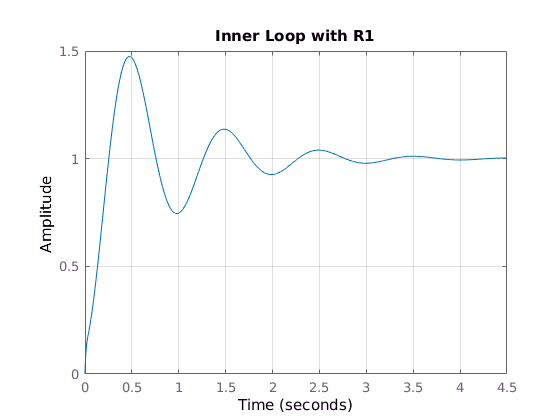

Li1 = R1 * Mixer * PitchRateModel;
Inner1 = Li1 / (1 + Li1);

Li2 = R2 * Mixer * PitchRateModel;
Inner2 = Li2 / (1 + Li2);

figure; step(Inner1); grid on; title('Inner Loop with R1');

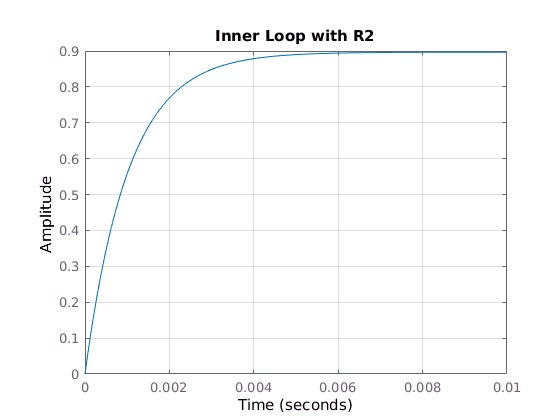

figure; step(Inner2); grid on; title('Inner Loop with R2');

## Step 2: Outer Loop

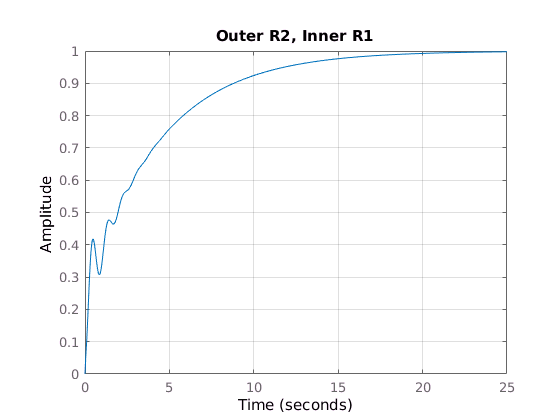

Lo12 = R2 * Inner1 * integrator;
Outer12 = Lo12 / (1 + Lo12);

Lo21 = R1 * Inner2 * integrator;
Outer21 = Lo21 / (1 + Lo21);

figure; step(Outer12); grid on; title('Outer R2, Inner R1');

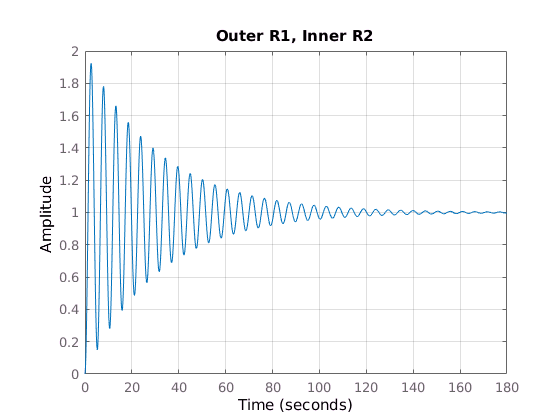

figure; step(Outer21); grid on; title('Outer R1, Inner R2');

## Step 3: Looking at the test input sequence

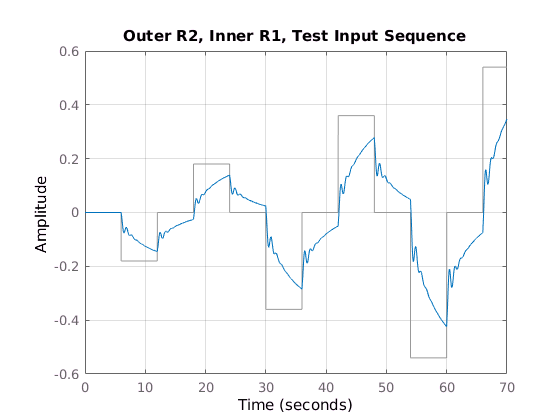

figure; 
    lsim(Outer12, test_input_ts.signals.values, test_input_ts.time); 
    grid on; title('Outer R2, Inner R1, Test Input Sequence');

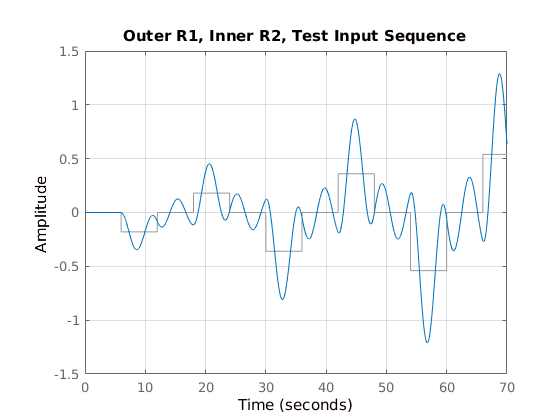

    
figure; 
    lsim(Outer21, test_input_ts.signals.values, test_input_ts.time); 
    grid on; title('Outer R1, Inner R2, Test Input Sequence');    